# 4. Identification of tank outlet area $a$ and height datum $h_0$

## Procedure

For a bottom tank, from the dynamics of the network the condition for constant water level of a tank, assuming it does not receive water from the tank above it, is given by

$a\sqrt{2gh} = \gamma k u$.

The water level is given by 

$h = (dh/dr) r+h_0$.

**WARNING**: $h_0$ and $h$ are measured relatively to the valve outlet hole, not the bottom of the tank or the zero of the sensor ruler.

Thus, from both equations

$r = \frac{\gamma^2k^2}{2ga^2(dh/dr)}u^2- \frac{h_0}{dh/dr}$.

Thus, from the linear regression of $r(u^2)$ with samples of $r$ and $u$, one obtains

$r= \alpha u^2 +  \beta$,

then

$a =  \gamma k  \frac{1}{ \sqrt{2g \alpha (dh/dr)}}$, and $h_0 = - \beta (dh/dr)$

1 . Open '**identification_sl.slx**';

For each tank:

2. Measure the steady-state resistor ratio values $r$ for various contant input actions $u$;

3. Find $\alpha$ and $\beta$ from the linear regression of $r(u^2)$;

4. Compute $a$ and $h_0$

## Initialization

clear;
% Load required identification contants
load("./data/pump.mat",'k');
load("./data/gamma.mat",'gamma');
load("./data/g.mat");
load('./data/dh_dr.mat');

## Tank 1

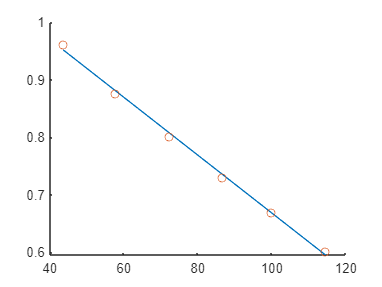

% Steady-state r vs input
u = [6.6;7.6;8.5;9.3;10.0;10.7];
% r = R_sense/R_ref
r = [0.9604;0.8761;0.8017;0.7303;0.6683;0.6013];
% Remove outliers
r_out = r(:);
u_out = u(:);
% Compute linear regression
reg = [ones(size(u_out.^2,1),1) u_out.^2]\r_out; 
% Plot data with regression
figure;
hold on;
plot(min(u_out.^2):0.1:max(u_out.^2),(min(u_out.^2):0.1:max(u_out.^2))*reg(2)+reg(1));
scatter(u.^2,r);
hold off;

% Compute h0
h01 = -reg(1)*dh_dr(1)

h01 = 43.4172

% Compute a
a1 = gamma(1)*k(1)*sqrt(1/(dh_dr(1)*2*g*reg(2)))

a1 = 0.1241

## Tank 2

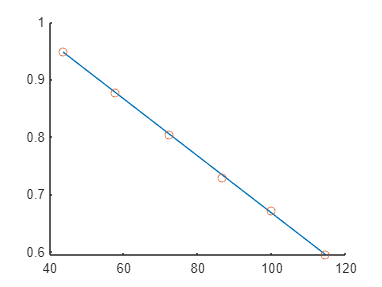

% Steady-state r vs input
u = [6.6;7.6;8.5;9.3;10.0;10.7];
% r = R_sense/R_ref
r = [0.9495;0.8767;0.8036;0.7289;0.6724;0.5944];
% Remove outliers
r_out = r(:);
u_out = u(:);
% Compute linear regression
reg = [ones(size(u_out.^2,1),1) u_out.^2]\r_out; 
% Plot data with regression
figure;
hold on;
plot(min(u_out.^2):0.1:max(u_out.^2),(min(u_out.^2):0.1:max(u_out.^2))*reg(2)+reg(1));
scatter(u.^2,r);
hold off;

% Compute h0
h02 = -reg(1)*dh_dr(2)

h02 = 41.1268

% Compute a
a2 = gamma(2)*k(2)*sqrt(1/(dh_dr(2)*2*g*reg(2)))

a2 = 0.1350

## Tank 3

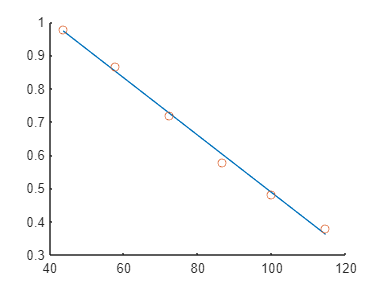

% Steady-state r vs input
u = [6.6;7.6;8.5;9.3;10.0;10.7];
% r = R_sense/R_ref
r = [0.9760;0.8657;0.7193;0.5789;0.4828;0.3796];
% Remove outliers
r_out = r(:);
u_out = u(:);
% Compute linear regression
reg = [ones(size(u_out.^2,1),1) u_out.^2]\r_out; 
% Plot data with regression
figure;
hold on;
plot(min(u_out.^2):0.1:max(u_out.^2),(min(u_out.^2):0.1:max(u_out.^2))*reg(2)+reg(1));
scatter(u.^2,r);
hold off;

% Compute h0
h03 = -reg(1)*dh_dr(3)

h03 = 46.9865

% Compute a
a3 = (1-gamma(2))*k(2)*sqrt(1/(dh_dr(3)*2*g*reg(2)))

a3 = 0.0333

## Tank 4

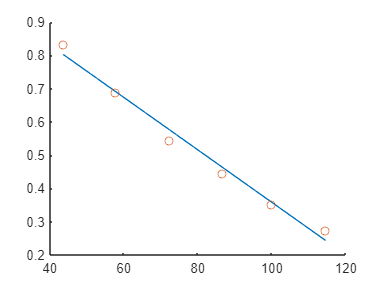

% Steady-state r vs input
u = [6.6;7.6;8.5;9.3;10.0;10.7];
% r = R_sense/R_ref
r = [0.8319;0.6895;0.5437;0.4446;0.3529;0.2731];
% Remove outliers
r_out = r(:);
u_out = u(:);
% Compute linear regression
reg = [ones(size(u_out.^2,1),1) u_out.^2]\r_out; 
% Plot data with regression
figure;
hold on;
plot(min(u_out.^2):0.1:max(u_out.^2),(min(u_out.^2):0.1:max(u_out.^2))*reg(2)+reg(1));
scatter(u.^2,r);
hold off;

% Compute h0
h04 = -reg(1)*dh_dr(4)

h04 = 39.3452

% Compute a
a4 = (1-gamma(1))*k(1)*sqrt(1/(dh_dr(4)*2*g*reg(2)))

a4 = 0.0331

## Save data

a = [a1; a2; a3; a4];
h0 = [h01; h02; h03; h04];
save("./data/a_hole.mat","a");
save('./data/h0.mat','h0');
